# KPI Analysis

This script is for evaluating the demand flexibility performance using the post processed data.

## 👤 User inputs

clc; clear all;

% Specify the testbed to be evaluated
TESTBEDs = {'IBAL', 'ASHP', 'WSHP'};
TESTBED = TESTBEDs{2};

## 🚀 Initialization and load data

% Add path to the subfunctions
addpath(fullfile(pwd,'subfunc'));

% Data folder
dataFolder = fullfile(pwd,TESTBED);

% Find all 'data.csv' files under the base folder, including subfolders
files = dir(fullfile(dataFolder, '**', 'data.csv'));

% Loop through all files
for i = 1:length(files)
    
    % Read the CSV file into a table
    dataTable = readtable(fullfile(files(i).folder, files(i).name));
    
    % Construct variable name from the path
    relativePath = strrep(files(i).folder, dataFolder, ''); % Remove base path
    relativePath = strrep(relativePath, '\', '.'); % Replace file separators with dots
    if startsWith(relativePath, '.')
        relativePath = extractAfter(relativePath, 1); % Remove leading dot
    end
    
    % Use eval to dynamically create the variable in the base workspace
    evalin('base', ['allCases.' relativePath '.data = dataTable;']);
    
end

## ⭐ Stand-alone KPI calculations

% Get location names
LOCs = fieldnames(allCases);

% Loop through locations
for i = 1:length(LOCs)
    
    % Current location
    LOC = LOCs{i};
    
    % Get GEB names
    GEBs = fieldnames(allCases.(LOC));
    
    % Loop through GEBs
    for j = 1:length(GEBs)
        
        % Current GEB
        GEB = GEBs{j};
        
        % Get variant names
        VARs = fieldnames(allCases.(LOC).(GEB));
        
        % Loop through all variants
        for k = 1:length(VARs)
            
            % Current variant
            VAR = VARs{k};
            
            % For TES data, evaluation window shall be from 8pm of previous day to 8pm of the testing day
            if contains(VAR, 'TES')
                allCases.(LOC).(GEB).(VAR).data = allCases.(LOC).(GEB).(VAR).data(1:1440,:);
            end
            
            % Load data
            data = allCases.(LOC).(GEB).(VAR).data;

            % HVAC power
            switch TESTBED
                
                case 'IBAL'
                    pwr_comps = {'ch1_power','ch2_power','pump1_power','pump2_power','pump3_power','pump4_power',...
                        'ahu1_fan_power','ahu2_fan_power','vav1_heat_power','vav2_heat_power','vav3_heat_power','vav4_heat_power'};
                    Q{1} = zeros(height(data), 1);
                    for comp_i = 1:length(pwr_comps)
                        Q{1} = Q{1} + data.(pwr_comps{comp_i});
                    end
                    ahu1_fan_power = data.ahu1_fan_power;
                    ahu2_fan_power = data.ahu2_fan_power;
                    ahu1_fan_sp_inh2o = data.ahu1_fan_sp_inh2o;
                    ahu2_fan_sp_inh2o = data.ahu2_fan_sp_inh2o;
                    
                case 'ASHP'
                    Q{1} = data.id_power + data.od_power;
                    
                case 'WSHP'
                    Q{1} = data.wshp_power;
                    zn_temp_cspt = data.zn_temp_cspt;
                    zn_temp_hspt = data.zn_temp_hspt;
                    zn_temp_sim = data.zn_temp_sim;
                
            end
            

            % Identify and sum 'occ##' heater power fields
            dataFields = fieldnames(data); 
            occFields = dataFields(startsWith(dataFields, 'occ') & ...
                endsWith(dataFields, 'ph_power')); 

            % Personal equipment power
            Q{2} = 0; 
            for occField = occFields'
                Q{2} = Q{2} + data.(occField{1});
            end

            % Identify and sum 'occ##' fan power fields
            dataFields = fieldnames(data); 
            occFields = dataFields(startsWith(dataFields, 'occ') & ...
                endsWith(dataFields, 'pf_power')); 

            % Personal equipment power
            Q{3} = 0; 
            for occField = occFields'
                Q{3} = Q{3} + data.(occField{1});
            end
            
            % Total power
            Q{4} = Q{1} + Q{2} + Q{3};
            
            % KPI: ENERGY USE

            E(1) = sum(Q{1})/60/1000;    % HVAC
            E(2) = sum(Q{2})/60/1000;    % Personal Heater
            E(3) = sum(Q{3})/60/1000;    % Personal Fan
            E(3) = E(1) + E(2) + E(3);     % Total
            
            % If a corresponding shedding or shifting case exist, calculate other KPIs
            if isfield(allCases.(LOC).Shed, VAR) || isfield(allCases.(LOC).Shift, VAR)

                % If the shifting case exist, extract the price signal, and infer the peak
                if isfield(allCases.(LOC).Shift, VAR) 
                    grid_signal_price = allCases.(LOC).Shift.(VAR).data.grid_signal_price;
                    grid_signal_shed_inferred = (grid_signal_price == max(grid_signal_price));
                end  
                
                % If the shedding case exist, extract the shed signal
                if isfield(allCases.(LOC).Shed, VAR)
                    grid_signal_shed = allCases.(LOC).Shed.(VAR).data.grid_signal_shed;
                    % Return a warning if actual and inferred do not match
                    if any(grid_signal_shed ~= grid_signal_shed_inferred)
                        warning('Postprocessing errors in %s - %s - %s.', LOC, GEB, VAR);
                    end
                else
                    grid_signal_shed = grid_signal_shed_inferred;
                end
                
                % Peak and nonpeak periods
                isPeak = grid_signal_shed == 1;
                isNonpeak = grid_signal_shed == 0;                

                % Peak power array
                Q_peak{1} = Q{1}(isPeak);
                Q_peak{2} = Q{2}(isPeak);
                Q_peak{3} = Q{3}(isPeak);
                Q_peak{4} = Q{4}(isPeak);

                % Nonpeak power array
                Q_nonpeak{1} = Q{1}(isNonpeak);
                Q_nonpeak{2} = Q{2}(isNonpeak);
                Q_nonpeak{3} = Q{3}(isNonpeak);
                Q_nonpeak{4} = Q{4}(isNonpeak);
                
                % KPI: AVERAGE PEAK DEMAND
                Q_peak_avg(1) = mean(Q{1}(isPeak))/1000;
                Q_peak_avg(2) = mean(Q{2}(isPeak))/1000;
                Q_peak_avg(3) = mean(Q{3}(isPeak))/1000;
                Q_peak_avg(4) = mean(Q{4}(isPeak))/1000;

                % KPI: FLEXIBILITY FACTOR
                for ii = 1:4
                    x1 = Q{ii}(isNonpeak);
                    x2 = length(Q{ii}(isNonpeak))/60;
                    x3 = Q{ii}(isPeak);
                    x4 = length(Q{ii}(isPeak))/60;
                    FF(ii) = kpi_flex_factor(x1,x2,x3,x4);
                end
                
                % KPI: TOU COST
                if isfield(allCases.(LOC).Shift, VAR)  
                    for ii = 1:4
                        if strcmp(LOC, 'NewYorkCity')
                            x1 = Q{ii}(isPeak)/1000.0;
                            x2 = Q{ii}(isNonpeak)/1000.0;
                            x3 = max(grid_signal_price);
                            x4 = min(grid_signal_price);
                            cost(ii) = kpi_tou_cost_aasc2_oneday(x1,x2,x3,x4)/30;  % assuming 30 days in a billing cycle
                        else
                            x1 = Q{ii}/1000.0;
                            x2 = grid_signal_price;
                            x3 = 1/60;
                            cost(ii) = kpi_tou_cost_acc(x1,x2,x3);
                        end
                    end
                end
                
            end

            % Identify and sum 'occ##' comfort fields
            dataFields = fieldnames(data); 
            occFields = dataFields(startsWith(dataFields, 'occ') & ...
                endsWith(dataFields, 'comfort')); 
            
            % Extract comfort data
            comfortData = [];
            for occField = occFields'
                comfortData = [comfortData, data.(occField{1})];
            end
            
            % KPI: PER OCC DISCOMFORT DURATION
            occ_cold = sum(comfortData == -1, 'all') / size(comfortData, 2);
            occ_warm = sum(comfortData == 1, 'all') / size(comfortData, 2);

            % Identify and sum 'occ##' heater usage fields
            dataFields = fieldnames(data); 
            occFields = dataFields(startsWith(dataFields, 'occ') & ...
                endsWith(dataFields, 'ph')); 
            
            % Extract comfort data
            heaterUsage = [];
            for occField = occFields'
                heaterUsage = [heaterUsage, data.(occField{1})];
            end

            % Identify and sum 'occ##' fan usage fields
            dataFields = fieldnames(data); 
            occFields = dataFields(startsWith(dataFields, 'occ') & ...
                endsWith(dataFields, 'pf')); 
            
            % Extract comfort data
            fanUsage = [];
            for occField = occFields'
                fanUsage = [fanUsage, data.(occField{1})];
            end
            
            % KPI: PER OCC PERSONAL EQUIP USAGE
            PHeat = sum(heaterUsage == 1, 'all') / size(heaterUsage, 2);
            PFan = sum(fanUsage == 1, 'all') / size(fanUsage, 2);
            
            % Store KPIs
            store_var_labels = {'Q_peak_avg', 'E', 'FF', 'cost', 'Q_peak', 'Q_nonpeak',...
                'occ_cold', 'occ_warm', 'PHeat', 'PFan'};
            for store_var_label = store_var_labels
                eval(['allCases.(LOC).(GEB).(VAR).kpi.' store_var_label{1} ' = ' store_var_label{1} ';']);
            end
            
            % Store time series
            switch TESTBED
                case 'IBAL'
                    store_var_labels = {'Q', 'ahu1_fan_power', 'ahu2_fan_power', 'ahu1_fan_sp_inh2o', 'ahu2_fan_sp_inh2o'};
                case 'WSHP'
                    store_var_labels = {'Q', 'grid_signal_price', 'zn_temp_cspt', 'zn_temp_hspt', 'zn_temp_sim'};
            end
            for store_var_label = store_var_labels
                eval(['allCases.(LOC).(GEB).(VAR).TS.' store_var_label{1} ' = ' store_var_label{1} ';']);
            end            
        end
        
    end
    
end

## 📊 Outputs

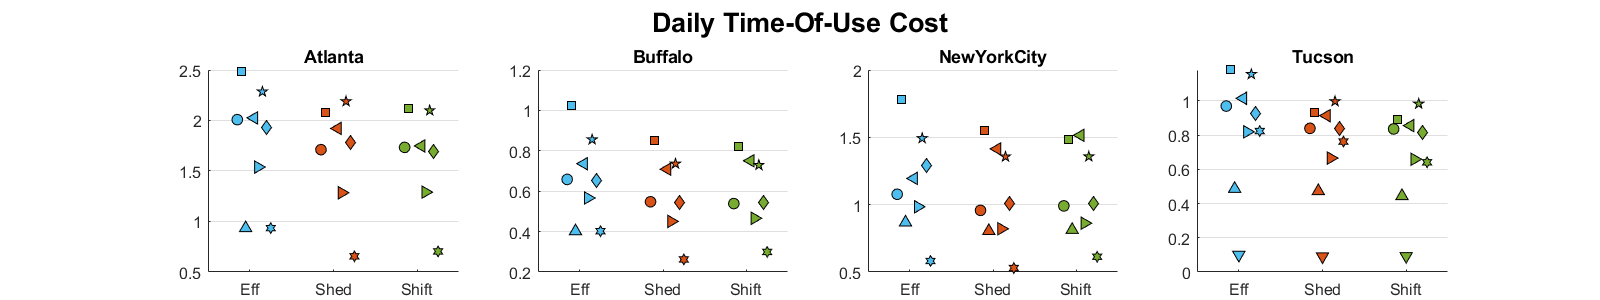

% Select which KPI to putput
KPI = 'cost'; KPI_name = 'Daily Time-Of-Use Cost'; KPI_unit = 'USD [$]';
% KPI = 'E'; KPI_name = 'Daily Energy Use'; KPI_unit = 'Energy [kWh]';
% KPI = 'Q_peak_avg'; KPI_name = 'Average Peak Demand'; KPI_unit = 'Power [kW]';
% KPI = 'FF'; KPI_name = 'Daily Flexibility Factor'; KPI_unit = '';

% Select which equipment for KPI calculation
INDEX = 1;
% INDEX_labels = {'HVAC', 'Personal Heater', 'Personal Fan', 'Total'};
% KPI_title = [INDEX_labels{INDEX} ' ' KPI_name];

% Occupant related KPIs
% KPI = 'occ_cold'; KPI_name = 'Daily Cold Discomfort Duration per Occupant'; KPI_unit = 'Minutes';
% KPI = 'occ_warm'; KPI_name = 'Daily Warm Discomfort Duration per Occupant'; KPI_unit = 'Minutes';
% KPI = 'PHeat'; KPI_name = 'Daily Per Occupant Heater Usage'; KPI_unit = 'Minutes';
% KPI = 'PFan'; KPI_name = 'Daily Per Occupant Fan Usage'; KPI_unit = 'Minutes';

KPI_title = KPI_name;

% List of varaints
markers = ['o', 's', '^', 'v', '<', '>', 'p', 'd', 'h', '*'];

% List of colors
color{1} = [0.3010, 0.7450, 0.9330];
color{2} = [0.8500, 0.3250, 0.0980];
color{3} = [0.4660, 0.6740, 0.1880];

% Create a new figure
figure;
set(gcf, 'Position', [100, 100, 1600, 300]);

% Get location names
LOCs = fieldnames(allCases);

% Loop through locations
for i = 1:length(LOCs)
    
    % Current location
    LOC = LOCs{i};
    
    % Get GEB names
    GEBs = fieldnames(allCases.(LOC));
    
    for j = 1:length(GEBs)
        
        % Current GEB
        GEB = GEBs{j};
        
        % Variation of each testbed
        switch TESTBED
            case 'IBAL'
                VARs = {'Default', 'ExtrmSum', 'TypShldr', 'ExtrmWin',...
                'MPC', 'STD2019', 'DenseOcc', 'EnergySave', 'TES', 'MPCTES'};  
            case 'ASHP'
                VARs = {'Default', 'ExtrmSum', 'TypShldr', 'ExtrmWin',...
                'MPC', 'STD2019', 'DenseOcc', 'EnergySave', 'TES'};     
            case 'WSHP'
                VARs = {'Default', 'ExtrmSum', 'TypShldr', 'ExtrmWin',...
                'MPC', 'STD2019', 'DenseOcc', 'EnergySave', 'TES'};   
        end
        
        % Initialize array to store values for the current GEB
        eval([GEB ' = zeros(length(VARs),1);']);
    
        for k = 1:length(VARs)
            
            % Current variant
            VAR = VARs{k};
            
            % Get value
            if isfield(allCases.(LOC).(GEB), VAR)
                if isfield(allCases.(LOC).(GEB).(VAR), 'kpi')
                    kpi_values = allCases.(LOC).(GEB).(VAR).kpi.(KPI);
                    kpi_value = kpi_values(INDEX);
                    if isfield(allCases.(LOC).(GEB), VAR)
                        eval([GEB '(k,1) = kpi_value;']);
                    else
                        eval([GEB '(k,1) = nan;']);
                    end
                else
                    eval([GEB '(k,1) = nan;']);
                end
            else
                eval([GEB '(k,1) = nan;']);
            end
            
        end
        
        % Store all results for the current location
        eval(['KPI_table_row.(LOC).(GEB) = ' GEB ';']);
        
    end
    
    % Plot for the current location
    subplot(1,4,i);
    hold on;
    for idx = 1:length(Eff)
        if ~isnan(Eff(idx))
            plot(0.8+0.05*idx, Eff(idx), markers(idx),...
                'MarkerSize', 8, 'MarkerFaceColor', color{1}, 'MarkerEdgeColor', 'k');
        end
    end
    for idx = 1:length(Shed)
        if ~isnan(Shed(idx))
            plot(1.8+0.05*idx, Shed(idx), markers(idx),...
                'MarkerSize', 8, 'MarkerFaceColor', color{2}, 'MarkerEdgeColor', 'k');
        end
    end
    for idx = 1:length(Shift)
        if ~isnan(Shift(idx))
            plot(2.8+0.05*idx, Shift(idx), markers(idx),...
                'MarkerSize', 8, 'MarkerFaceColor', color{3}, 'MarkerEdgeColor', 'k');
%             set(line, 'HandleVisibility', 'off'); 
        end
    end
    xlim([0.5, 3.5]); 
    title(LOC);
    grid on;
    set(gca, 'XGrid', 'off', 'YGrid', 'on');
    set(gca, 'XTick', [1:3], 'XTickLabel', {'Eff', 'Shed', 'Shift'}, 'FontSize', 12);

end

% Add a title to the entire figure
sgtitle(KPI_title, 'FontSize', 20, 'FontWeight', 'bold');


% KPI table
KPI_table = [];

% Get location names
LOCs = fieldnames(allCases);

% Loop through locations
for i = 1:length(LOCs)
    
    % Current location
    LOC = LOCs{i};
    
    % Get GEB names
    GEBs = fieldnames(allCases.(LOC));
    
    for j = 1:length(GEBs)
        
        % Current GEB
        GEB = GEBs{j};

        % Row index
        if strcmp(GEB, 'Mod')
            continue;
        end
        
        % Append to table
        KPI_table = [KPI_table; KPI_table_row.(LOC).(GEB)'];
        
    end
    
end